MAX_DATASET_SIZE = 7131


ans = 

  Map with properties:

        Count: 0
      KeyType: char
    ValueType: any



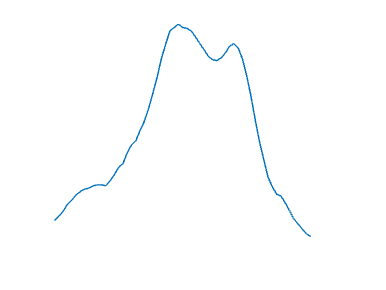

Index in position 1 exceeds array bounds. Index must not exceed 7130.

MAX_DATASET_SIZE = 7131

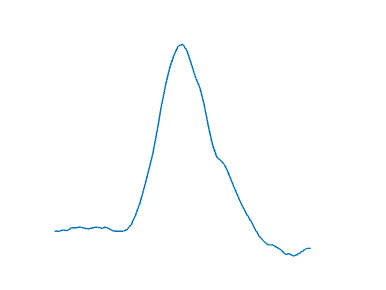


%build up QRS image dataset
%@GRIMD_FOR_MAP@
for i=1:MAX_DATASET_SIZE
    raw_data = masterQRS(i,[1:61]);
    plot(raw_data);
    box off
    axis off
    FILENAME = strcat("DATASET","/QRS/qrs_",int2str(i),".png");
    saveas(gcf,FILENAME);

end

%build up PVC image dataset
%@GRIMD_FOR_MAP@
for i=1:MAX_DATASET_SIZE
    raw_data = masterPVC(i,[1:61]);
    plot(raw_data);
    box off
    axis off
    FILENAME = strcat("DATASET","/NOQRS/no_qrs_",int2str(i),".png");
    saveas(gcf,FILENAME);

end
